## ベクトル場の可視化

参考：https://www.math.kyoto-u.ac.jp/~karel/files/notes_biseki2matlab_2018.pdf

### 
$$\frac{\mathrm{dx}}{\mathrm{dt}}=x\left(1-x\right)$$


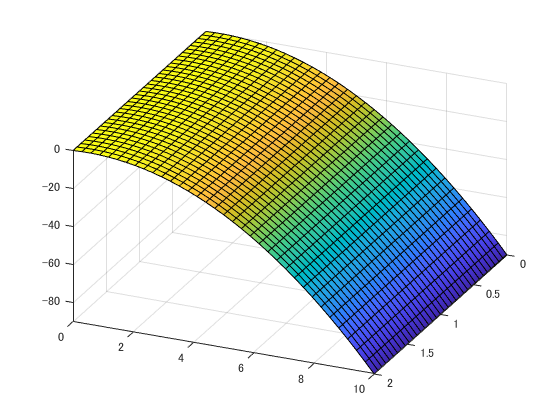

% 微分方程式を定義
f = @(t,x) x.*(1-x);    % ソルバーで解く為には引数を(t,x0,x1...)の順にする必要がある
fsurf(f, [0,2,0,10]);
view([113.8 37.2]);

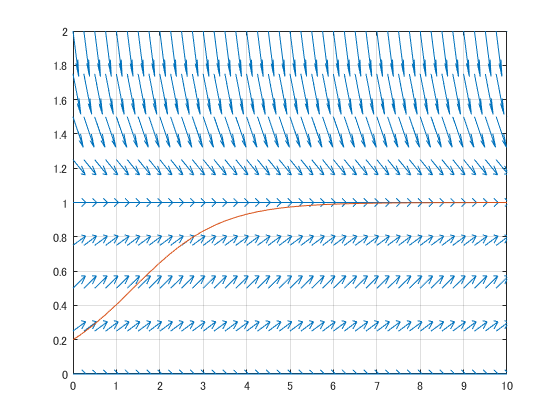


% 格子点の定義
t = 0:0.25:10;
x = 0:0.25:2;
[T,X] = meshgrid(t,x);

% 各格子点での勾配を計算
dT = ones(size(T));
dX = f(T,X);

% 矢印の長さを正規化
N = sqrt(dT.^2+dX.^2);
dT = dT./N;
dX = dX./N;

% プロット
% 各インデックスnについて、座標(T(n),X(n))で矢印(dT(n),dX(n))を描画する
quiver(T,X,dT,dX);

% 初期条件を与えて解を求める
tspan = [0,10];
y0 = 0.2;
[xs, ys] = ode45(f, tspan, y0);
hold on;
plot(xs, ys);
xlim(tspan);
ylim([0,2]);
grid on;
hold off;